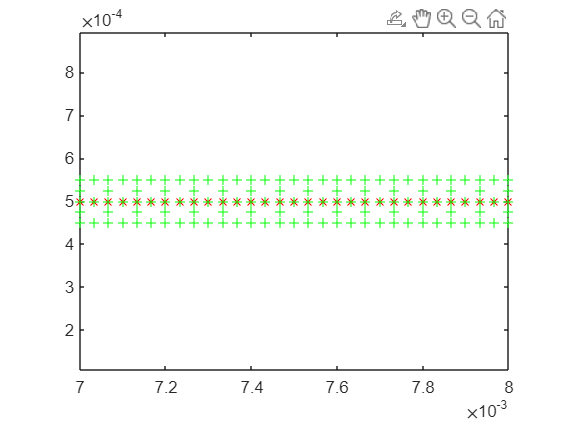

figure()

[x,y] = xy(crack,Coordinate);
plot(x,y,'r*')

hold on
[xe,ye] = xy(crack_e,Coordinate,Ielement);
plot(xe,ye,'g+')
hold off
axis equal

function [x,y] = xy(subject,Coordinate,Ielement)
%% 获得单元/节点的xy坐标
%  input数目：2为节点；3为单元

if nargin == 2
	x = Coordinate(subject,1);
	y = Coordinate(subject,2);
end
if nargin == 3
	node = unique(Ielement(subject,:));
	x = Coordinate(node,1);
	y = Coordinate(node,2);
end
end